# Power & coherence analyses (with artefact removal)

Script test for inputing my original data (before artefact removal) 

close all
clear

% set up variable for loading 
pathway_source = 'F:\MatlabData';
session_name = 'HAB3'

session_name = 'HAB3'

subsession_name = 'empty';

saving_folder = 'first_AW'

saving_folder = 'first_AW_1min'

saving_path = fullfile('E:\Documents\LNCA\Résultats\Electrophy4\Resutats_2021-22',saving_folder,session_name)

saving_path = 'E:\Documents\OneDrive\LNCA\Résultats\Electrophy4\Resutats_2021-22\first_AW_1min\HAB3'

% load the managing data (resume the number of rats)
load(fullfile(pathway_source,'managingRat.mat'));

% selection the session to analyse
session_list = categorical(managingRat(2,:));
subsession_list = categorical(managingRat(3,:));

n=1;
for i = 1:length(session_list)
    if session_list(1,i) == session_name & subsession_list(1,i) == subsession_name % & managingRat{1,i} ~= 14
        managing_sorted(:,n)= managingRat(:,i);
        n = n+1;
    end
end

### Load the data, and put them (all) together for processing 

This function can be found at the end of the script for now 

[LFP, table_nb_period,srate] = extract_the_data(managing_sorted,pathway_source, session_name,subsession_name);

current_rat = 16

current_rat = 17

current_rat = 18

current_rat = 19

current_rat = 13

current_rat = 33

current_rat = 32

current_rat = 31

current_rat = 30

current_rat = 28

table_nb_period = 10×4 table
          AW    CW    SWS    REM
          __    __    ___    ___

    16     6    16    22     12 
    17    10    23    21      4 
    18     9    18    13      3 
    19     5    11    11      7 
    13     7    26    18      7 
    33     3    16    17      9 
    32     5    19    15      7 
    31     7    15    17     12 
    30     8    18    14      8 
    28     2    10    11      8 



saving_path_temp = fullfile('E:\Documents\LNCA\Résultats\Electrophy4\Resutats_2021-22', saving_folder)

saving_path_temp = 'E:\Documents\OneDrive\LNCA\Résultats\Electrophy4\Resutats_2021-22\first_AW_1min'

name_file = sprintf("Number_of_period_by state_and_by_rat.xlsx")

name_file = "Number_of_period_by state_and_by_rat.xlsx"

writetable(table_nb_period,fullfile(saving_path_temp,name_file), 'WriteRowNames',true);

#### The function which select the part of the signal we want to process

This function can be found at the end of the script for now 

time = 60; %s

condition = "first" % eaher first, last, after

condition = "first"

wanted_state = "AW"

wanted_state = "AW"

after_state = "none" % None if not used by the condition

after_state = "none"


[LFP_full, Table_sumary] = selection_period(managing_sorted,LFP,srate,time, condition, wanted_state, after_state);

Rat n°16 = Episod number :  1 
Rat n°17 = Episod number :  1 
Rat n°18 = Episod number :  1 
Rat n°19 = Episod number :  1 
Rat n°13 = Episod number :  1 
Rat n°33 = Episod number :  1 
Rat n°32 = Episod number :  1 
Rat n°31 = Episod number :  1 
Rat n°30 = Episod number :  1 
Rat n°28 = Episod number :  1 


Table_sumary = 10×4 table
    Rats    Episod number    Episod start (s)    Episod length (s)
    ____    _____________    ________________    _________________

     16           1                 1                   892       
     17           1                 1                   982       
     18           1                 1                  1274       
     19           1                 1                  1344       
     13           1                 1                  1214       
     33           1                 1                   657       
     32           1                 1                   864       
     31           1                 1                  1820       
     30           1                 1                   587       
     28           1                 1                   877       




name_file = sprintf("Summary_table_of_episod_selected.xlsx")

name_file = "Summary_table_of_episod_selected.xlsx"

writetable(Table_sumary,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

Remouving the muscle from the LFP data (it is not needed)

LFP_full = LFP_full(1:5,:,:);

#### Computing the vector time + delete the not needed variables

dt = 1/srate;
tottime = length(LFP_full(1,:,1))/srate;
time = 0:dt:tottime-dt;

clear current_rat current_hour dt hour_list LFP0_Temp nameFile ...
    nameFolder1 nameFolder2 Results session_list SleepTrack subsession_list


### Remove the slow drift if possible

The fonction xomes from Chronux toolbox - as most of the function for signal processing

LFP_sld_full = [];
for rat = 1:length(managing_sorted(1,:))
LFP_sld = [];
for i=1:length(LFP_full(:,1,rat))
    LFP_sld_tp = locdetrend(LFP_full(i,:,rat),srate, [4 0.2]);
    LFP_sld = [LFP_sld; LFP_sld_tp'];
end
LFP_sld_full(:,:,rat)= LFP_sld;
end

clear LFP_sld LFP_sld_tp

### Artefact removal

Upsampling to better match the specification of the artefact removal paper

r = 25; % factor of the increase of the sampling rate

LFP_upsampled_full = [];
for rat = 1:length(managing_sorted(1,:))
LFP_upsampled=[];
for i=1:length(LFP_full(:,1,rat))
    LFP_upsampled = [LFP_upsampled; interp(LFP_sld_full(i,:,rat),r)];
end
LFP_upsampled_full(:,:,rat)= LFP_upsampled;
end

disp('The temporally sampling rate is :')

The temporally sampling rate is :


temp_srate = srate*r

temp_srate = 6875

#### Artefact removal

 Amir Rastegarnia, Anh Tuan Nguyen, and Zhi Yang.  Artifact characterization and removal for in vivo neural recording. Journal of neuroscience methods 226 (2014): 110-123. Original script modify by Vincent Douchamps & myself

LFP_cleaned_full = [];
for rat = 1:length(managing_sorted(1,:))
LFP_cleaned = [];
for i=1:length(LFP_full(:,1,rat))
    [data_new_temp, ~] = artifact_removal_inVivo_VD(LFP_upsampled_full(i,:,rat), temp_srate);
    LFP_cleaned = [LFP_cleaned; data_new_temp];
end
LFP_cleaned_full(:,:,rat)= LFP_cleaned;
end


Dowsampling - because it is too high to manage easily

LFP_cleaned_down_full = [];
for rat = 1:length(managing_sorted(1,:))
LFP_cleaned_down=[];
for i=1:length(LFP_cleaned_full(:,1,rat))
    LFP_cleaned_down = [LFP_cleaned_down; decimate(LFP_cleaned_full(i,:,rat),r)];
end
LFP_cleaned_down_full(:,:,rat)= LFP_cleaned_down;
end

Put the data into a better name variable and delete what is not needed

LFP_cl_full = LFP_cleaned_down_full;

clear LFP_cleaned LFP_cleaned_down LFP_cleaned_down_full LFP_cleaned_full ...
    LFP_sld_full LFP_upsampled LFP_upsampled_full lfpSampRemoved_arteFree ...
    r temp_srate

### Figure after artefact removal of the raw data

figure showing the effect of the artefact removal on only on rat at a time

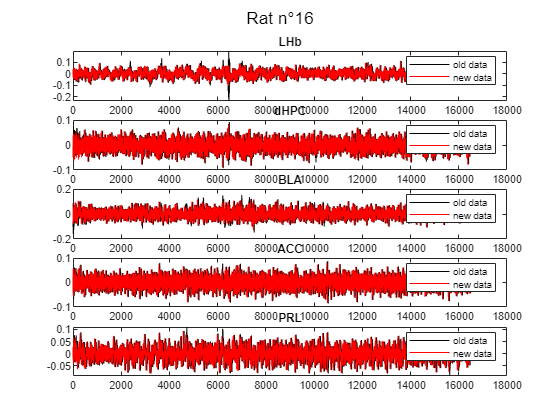

rat = 1; % position in the matrix

figure 
subplot(511)
plot(LFP_full(1,:,rat), 'k'); hold on
plot(LFP_cl_full(1,:,rat), 'r')
legend({'old data', 'new data'})
title('LHb')

subplot(512)
plot(LFP_full(2,:,rat), 'k'); hold on
plot(LFP_cl_full(2,:,rat), 'r')
legend({'old data', 'new data'})
title('dHPC')

subplot(513)
plot(LFP_full(3,:,rat), 'k'); hold on
plot(LFP_cl_full(3,:,rat), 'r')
legend({'old data', 'new data'})
title('BLA')

subplot(514)
plot(LFP_full(4,:,rat), 'k'); hold on
plot(LFP_cl_full(4,:,rat), 'r')
legend({'old data', 'new data'})
title('ACC')

subplot(515)
plot(LFP_full(5,:,rat), 'k'); hold on
plot(LFP_cl_full(5,:,rat), 'r')
legend({'old data', 'new data'})
title('PRL')


sgtitle(sprintf('Rat n°%d',managing_sorted{1,rat})) 

### Computing the spectrogram for the 5 channels

Still using Chronux toolbox - more efficent in time

% setting chronux paramiters
params.fpass = [1 80]; % in Hz (0.5 to 10) - 0.5 is minimum if we want to use a 4 sec window and see one cycle
params.Fs = 275;
k = 9; % num tapers (lower for less frequency leakage, higher for more leakage but smoother spectrum) % and it is a tradeoff with how many time points you have. spectrum is less smooth with many time points.
nw = (k+1)/2;
params.tapers=[nw k];
moving_win=4;
win_shift=0.2;
params.err =[1 0.01];


Stot=[]; ttot=[]; ftot=[];
for rat = 1:length(managing_sorted(1,:))
S=[]; t=[]; f=[];
for i=1:length(LFP_cl_full(:,1,rat))
    [S(:,:,i),t,f,Serr]=mtspecgramc(LFP_cl_full(i,:,rat),[moving_win win_shift],params);
end
Stot(:,:,:,rat) = S(:,:,:);
ttot = t;
ftot = f;
end


Compute the spectrogram plot

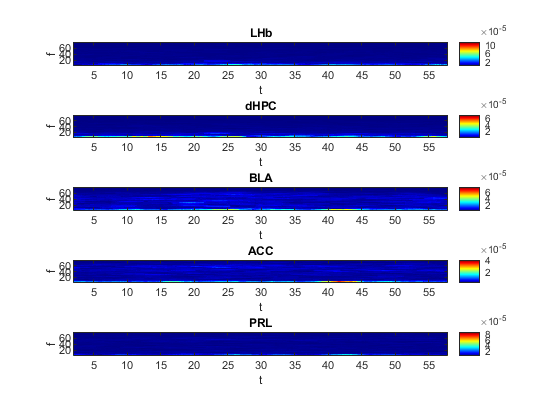

rat = 1; % position in the matrix

figure 
subplot(511)
plotsig(Stot(:,:,1,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;title('LHb')
subplot(512)
plotsig(Stot(:,:,2,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;title('dHPC')
subplot(513)
plotsig(Stot(:,:,3,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;title('BLA')
subplot(514)
plotsig(Stot(:,:,4,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;title('ACC')
subplot(515)
plotsig(Stot(:,:,5,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;title('PRL') 



clear S t f k nw rat

### Apply Z score

 z-scored within each frequency bin by taking mean and std of entire recording at that particular freq bin

Stot_Z=[];
for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    Stot_Z(:,:,i,rat) = bsxfun(@rdivide,bsxfun(@minus,Stot(:,:,i,rat),mean(Stot(:,:,i,rat),2)),std(Stot(:,:,i,rat),0,2));
end
end


Figure for the Z score spectrogram

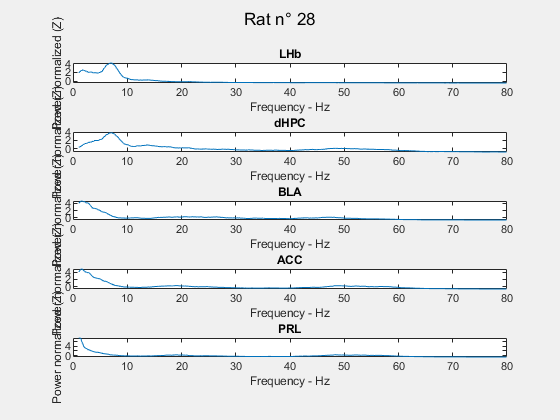

name_file = "spectro_power_by_f_rat_16.fig"

name_file = "spectro_power_by_f_rat_17.fig"

name_file = "spectro_power_by_f_rat_18.fig"

name_file = "spectro_power_by_f_rat_19.fig"

name_file = "spectro_power_by_f_rat_13.fig"

name_file = "spectro_power_by_f_rat_33.fig"

name_file = "spectro_power_by_f_rat_32.fig"

name_file = "spectro_power_by_f_rat_31.fig"

name_file = "spectro_power_by_f_rat_30.fig"

name_file = "spectro_power_by_f_rat_28.fig"

% spectrogram

titles = {'LHb', 'dHPC', 'BLA', 'ACC', 'PRL'};

% Figures for each rat whitout displaying it
fspect = figure('visible', 'off');
for rat = 1:length(managing_sorted(1,:))
    figure(fspect)
    clf(fspect)
    for i=1:length(LFP_full(:,1))
        subplot(5,1,i)
        plot(ftot,mean(Stot_Z(:,:,i,rat),1))
        title(titles{1,i})
        ylabel('Power normalized (Z)')
        xlabel('Frequency - Hz')
    end
    sgtitle(sprintf('Rat n° %d',managing_sorted{1,rat}))
    name_file = sprintf("spectro_power_by_f_rat_%d.fig",managing_sorted{1,rat})
    saveas(fspect,fullfile(saving_path,"Figure",name_file))
end

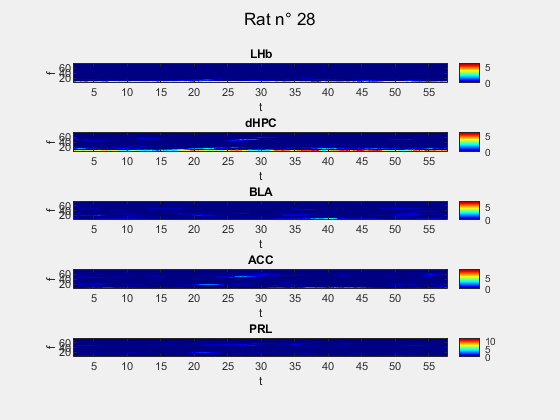

name_file = "spectro_f_by_t_rat_16.fig"

name_file = "spectro_f_by_t_rat_17.fig"

name_file = "spectro_f_by_t_rat_18.fig"

name_file = "spectro_f_by_t_rat_19.fig"

name_file = "spectro_f_by_t_rat_13.fig"

name_file = "spectro_f_by_t_rat_33.fig"

name_file = "spectro_f_by_t_rat_32.fig"

name_file = "spectro_f_by_t_rat_31.fig"

name_file = "spectro_f_by_t_rat_30.fig"

name_file = "spectro_f_by_t_rat_28.fig"



% spectrogram by time
% Figures for each rat whitout displaying it
fspectime = figure('visible', 'off');
for rat = 1:length(managing_sorted(1,:))
    figure(fspectime)
    clf(fspectime)
    for i=1:length(LFP_full(:,1))
        subplot(5,1,i)
        plotsig(Stot_Z(:,:,i,rat),0,ttot,ftot); axis xy; colorbar;colormap jet;
        title(titles{1,i})
    end
    sgtitle(sprintf('Rat n° %d',managing_sorted{1,rat}))
    name_file = sprintf("spectro_f_by_t_rat_%d.fig",managing_sorted{1,rat})
    saveas(fspectime,fullfile(saving_path,"Figure",name_file))
end


% clear the figure we dont need after 
clear fspect  fspectime

#### Figure from the mean of the power across the rats

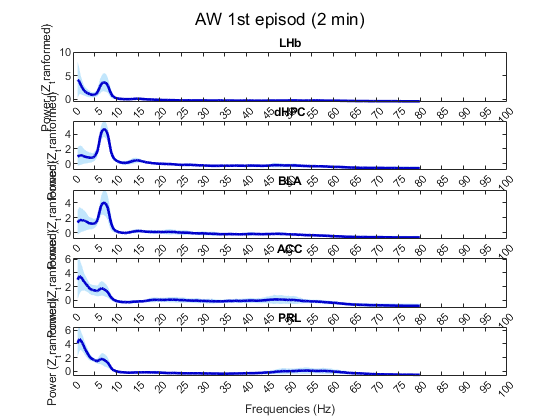

mean_power = [];

for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    mean_power(rat,:,i) = mean(Stot_Z(:,:,i,rat),1);
end
end

figspect_mean = figure;

for i=1:length(LFP_full(:,1))
    figure(figspect_mean)

    % Set plot paramiters
    option.color_area = rgb("LightSkyBlue");
    option.color_line = rgb("MediumBlue");
    option.x_axis = ftot;
    option.error = 'std';
    option.handle = gcf;
    option.alpha      = 0.5;
    option.line_width = 2;
    subplot(5,1,i)
    plot_areaerrorbar(mean_power(:,:,i), option) % function downloaded for mathsWorks (be carefull licence attached)
    
    xlim([0 100])
    xt = [0:5:100];                   % 'XTick' Values, bin between the number of the x axis
    set(gca, 'XTick', xt)             % Relabel 'XTick' With 'XTickLabel' Values
    xlabel('Frequencies (Hz)')
    ylabel('Power (Z_tranformed)')
    title(titles{1,i}) 
    sgtitle("AW 1st episod (2 min)")
end

hold off


name_file = sprintf("Mean_power_rat.fig")

name_file = "Mean_power_rat.fig"

saveas(figspect_mean,fullfile(saving_path,"Figure",name_file))

**Plot the mean of a spectrogram by time**

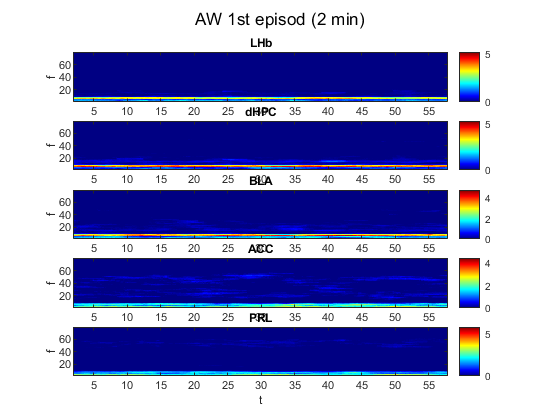

mean_power_time = [];
Spect_plot = [];


for i=1:length(LFP_full(:,1))
    mean_power_time(:,:,i) = mean(Stot_Z(:,:,i,:),4);
end

figspect_time_mean = figure;

for i=1:length(LFP_full(:,1))
    figure(figspect_mean)
    subplot(5,1,i)
    plotsig(mean_power_time(:,:,i),0,ttot,ftot); axis xy; colorbar;colormap jet;
    title(titles{1,i})

end

hold off


name_file = sprintf("Mean_power_byTime_rat.fig")

name_file = "Mean_power_byTime_rat.fig"

saveas(figspect_time_mean,fullfile(saving_path,"Figure",name_file))

## Theta band analysis

Checking if the frequency band we are looking for is present in the signal - use pick detection

### **Pick the frenquency band we want to analyse (eg: theta 5-9Hz):**

**gamma : 45-65Hz, delta = 1-3 Hz**

#### Low pass filter 

lpf = 9

lpf = 9

#### High pass filter 

hpf = 5

hpf = 5

#### General overview

peaks = {};
locs = {};
widths = {};
prominences = {};

for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    data =[];
    data = mean(Stot(:,:,i,rat,1));
    [peaks{i,1,rat},locs{i,1,rat}, widths{i,1}, prominences{i,1}] = findpeaks(data,'MinPeakProminence', 0.001);
end
end

Plot figure as example

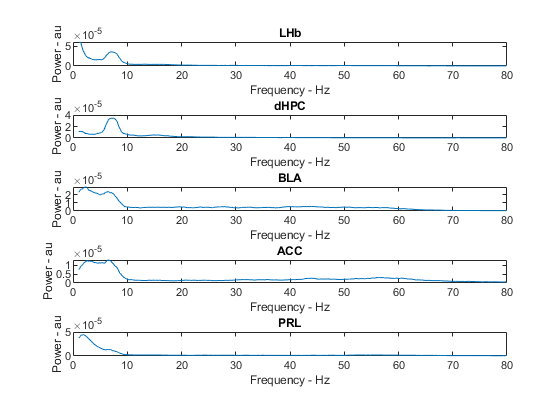

figure
titles = {'LHb','dHPC','BLA','ACC','PRL'};
rat = 1;
for i=1:length(LFP_full(:,1))
    subplot(5,1,i)
    plot(ftot,mean(Stot(:,:,i,rat),1),ftot(locs{i,1,rat}),peaks{i,1,rat},'or')
    title(titles{1,i})
    ylabel('Power - au')
    xlabel('Frequency - Hz')
end


clear widths peaks locs prominences data

#### Peak processing

% find the sampling rate in frequency
Fs_freq = length(ftot)/max(ftot)


Fs_freq = 7.3597

stop_freq_bd = round(lpf*Fs_freq);      %in points (positions)
start_freq_bd = round(hpf*Fs_freq);     %in points (positions)

Q=[];
data_WBG = [];
int_data_Z =NaN(length(managing_sorted(1,:)),5); % rat * channels

peaks = {};
locs = {};
widths = {};
prominences = {};

for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    data = [];
    data = mean(Stot_Z(:,start_freq_bd:stop_freq_bd,i,rat),1);
    [peaks{i,1},locs{i,1,rat}, widths{i,1}, prominences{i,1}] = findpeaks(data, 'MinPeakProminence', 0.1);
    
    data_Z = mean(Stot_Z(:,start_freq_bd:stop_freq_bd,i,rat));
    freq_new_scale = ftot(:,start_freq_bd:stop_freq_bd);
    
    if isempty(prominences{i,1}) == 0
        % clean the background
        data_WBG(:,i,rat) = data_Z - min(data_Z);
                
        % integrate under the area
        Q(:,i,rat) = cumtrapz(freq_new_scale,data_WBG(:,i,rat));
        int_data_Z(rat,i) = max(Q(:,i,rat));
        
    end
end
end

#### Evaluate the frequency at the peak 

peak_fq = zeros([length(managing_sorted(1,:)),5]);
for rat = 1:length(managing_sorted(1,:))
for i = 1:length(locs(:,1,rat))
    if isempty(locs{i,1,rat}) == 1
        peak_fq(rat,i) = NaN;
    else 
        peak_fq(rat,i) =  freq_new_scale(locs{i,1,rat}(1,1));
    end
end
end

Figure of the detected peaks - Figure representing the integrative area

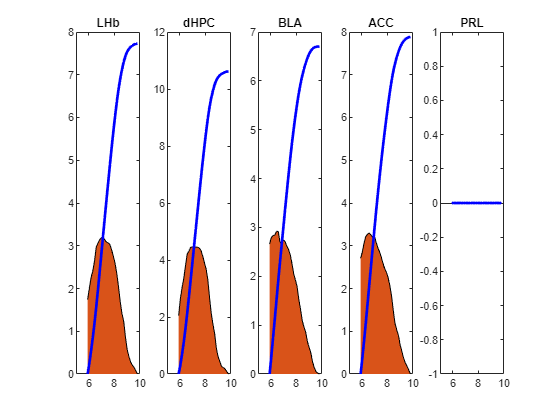

figure
rat = 1;
for i=1:length(LFP_full(:,1))
    subplot(1,5,i);
    plot(freq_new_scale, data_WBG(:,i,rat),'k'); hold on
    a = area(freq_new_scale,data_WBG(:,i,rat));
    plot(freq_new_scale, Q(:,i,rat),'b','LineWidth',2);
    title(titles{1,i});
end


clear widths peaks locs prominences data Q data_WBG data_Z freq_new_scale a stop_freq_bd start_freq_bd Fs_freq

## Export the data of the FFT in tables

list_rat = {};
for rat = 1:length(managing_sorted(1,:))
    list_rat{1,rat} = num2str(managing_sorted{1,rat});
end

T_power_theta = array2table(int_data_Z, 'VariableNames',titles ,'RowNames', list_rat) 

T_power_theta = 10×5 table
           LHb       dHPC      BLA       ACC       PRL  
          ______    ______    ______    ______    ______

    16    7.7282    10.616    6.7029     7.884       NaN
    17       NaN    9.4081    7.1639    2.3816    4.1791
    18    11.918     12.53    6.7398       NaN       NaN
    19     5.159    11.045    10.181    3.0209      2.46
    13    11.964    11.829    11.824    6.2616    6.5832
    33    2.6056    7.0885    11.923    5.0048      5.97
    32    6.7039    6.2856    9.9747    1.8263       NaN
    31    11.892    12.016    11.986    5.6927    8.6496
    30     10.68    10.383    11.664    6.5704    4.1629
    28

name_file = sprintf("Table_power_theta.xlsx")

name_file = "Table_power_theta.xlsx"

writetable(T_power_theta,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

T_peak_theta = array2table(peak_fq, 'VariableNames',titles ,'RowNames', list_rat) 

T_peak_theta = 10×5 table
           LHb       dHPC      BLA       ACC       PRL  
          ______    ______    ______    ______    ______

    16    7.1167    7.1167    6.5796    6.5796       NaN
    17       NaN    6.9824    6.8481    6.8481     6.311
    18    7.1167    7.1167    7.3853       NaN       NaN
    19    7.3853    7.1167    6.9824    6.8481    6.1768
    13     7.251    6.9824     7.251    6.5796    6.7139
    33    7.1167    7.1167    7.7881    7.6538    7.1167
    32    7.3853    7.5195    6.9824    6.9824       NaN
    31    7.5195    7.5195    7.5195    6.9824    6.7139
    30    6.9824    6.9824    7.1167    6.5796    6.1768
    28

name_file = sprintf("Table_peak_theta.xlsx")

name_file = "Table_peak_theta.xlsx"

writetable(T_peak_theta,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name),'WriteRowNames',true);



## **gamma band : 45-65Hz**

#### Low pass filter 

lpf = 65

lpf = 65

#### High pass filter 

hpf = 45

hpf = 45

#### General overview

peaks = {};
locs = {};
widths = {};
prominences = {};

for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    data =[];
    data = mean(Stot(:,:,i,rat,1));
    [peaks{i,1,rat},locs{i,1,rat}, widths{i,1}, prominences{i,1}] = findpeaks(data,'MinPeakProminence', 0.001);
end
end

Plot figure as example

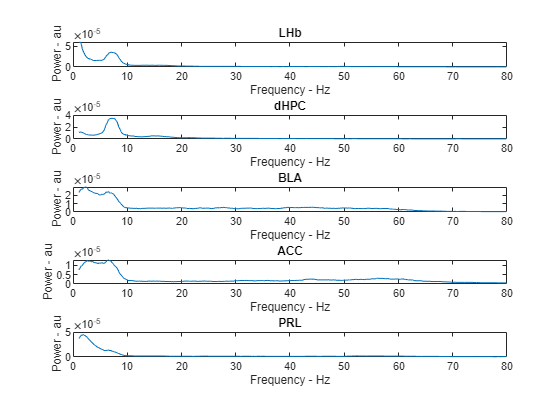

figure
titles = {'LHb','dHPC','BLA','ACC','PRL'};
rat = 1;
for i=1:length(LFP_full(:,1))
    subplot(5,1,i)
    plot(ftot,mean(Stot(:,:,i,rat),1),ftot(locs{i,1,rat}),peaks{i,1,rat},'or')
    title(titles{1,i})
    ylabel('Power - au')
    xlabel('Frequency - Hz')
end


clear widths peaks locs prominences data

#### Peak processing

% find the sampling rate
Fs_freq = length(ftot)/max(ftot)


Fs_freq = 7.3597

stop_freq_bd = round(lpf*Fs_freq);      %in points (positions)
start_freq_bd = round(hpf*Fs_freq);     %in points (positions)

Q=[];
data_WBG = [];
int_data_Z =NaN(length(managing_sorted(1,:)),5); % rat * channels

peaks = {};
locs = {};
widths = {};
prominences = {};

for rat = 1:length(managing_sorted(1,:))
for i=1:length(LFP_full(:,1))
    data = [];
    data = mean(Stot_Z(:,start_freq_bd:stop_freq_bd,i,rat),1);
    [peaks{i,1},locs{i,1,rat}, widths{i,1}, prominences{i,1}] = findpeaks(data, 'MinPeakProminence', 0.1);
    
    data_Z = mean(Stot_Z(:,start_freq_bd:stop_freq_bd,i,rat));
    freq_new_scale = ftot(:,start_freq_bd:stop_freq_bd);
    
    if isempty(prominences{i,1}) == 0
        % clean the background
        data_WBG(:,i,rat) = data_Z - min(data_Z);
                
        % integrate under the area
        Q(:,i,rat) = cumtrapz(freq_new_scale,data_WBG(:,i,rat));
        int_data_Z(rat,i) = max(Q(:,i,rat));
        
    end
end
end


#### Evaluate the frequency at the peak for later analyses

If there not value in locs, that means that no peak was detected so no oscillations in the frequency band we are looking for. 

peak_fq = zeros([length(managing_sorted(1,:)),5]);
for rat = 1:length(managing_sorted(1,:))
for i = 1:length(locs(:,1,rat))
    if isempty(locs{i,1,rat}) == 1
        peak_fq(rat,i) = NaN;
    else 
        peak_fq(rat,i) =  freq_new_scale(locs{i,1,rat}(1,1));
    end
end
end

Figure of the detected peaks - Figure representing the integrative area

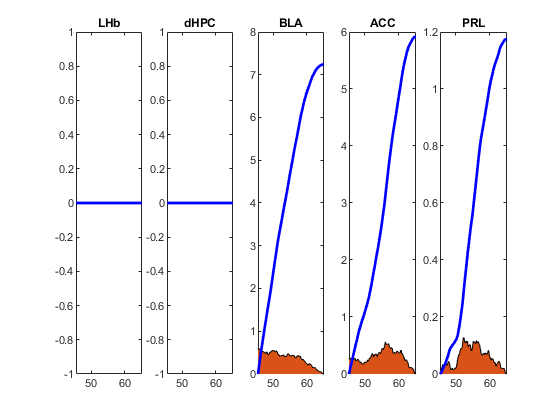

figure
rat = 1;
for i=1:length(LFP_full(:,1))
    subplot(1,5,i);
    plot(freq_new_scale, data_WBG(:,i,rat),'k'); hold on
    a = area(freq_new_scale,data_WBG(:,i,rat));
    plot(freq_new_scale, Q(:,i,rat),'b','LineWidth',2);
    title(titles{1,i});
end


clear widths peaks locs prominences data Q data_WBG data_Z freq_new_scale a stop_freq_bd start_freq_bd Fs_freq

## Export the data of the FFT in tables

data to save : 

- peak_fq = (m, 1)

- titles (# structures list) = (1, n)

list_rat = {};
for rat = 1:length(managing_sorted(1,:))
    list_rat{1,rat} = num2str(managing_sorted{1,rat});
end

T_power_gamma = array2table(int_data_Z, 'VariableNames',titles ,'RowNames', list_rat) 

T_power_gamma = 10×5 table
           LHb       dHPC      BLA       ACC       PRL  
          ______    ______    ______    ______    ______

    16       NaN       NaN    7.2415    5.9152    1.1754
    17       NaN       NaN       NaN       NaN       NaN
    18       NaN       NaN     10.61       NaN       NaN
    19       NaN    4.6036       NaN       NaN    14.516
    13    2.6172       NaN       NaN    8.9713    9.3753
    33    8.0331    7.4659    4.4093    17.858     2.152
    32       NaN    12.899    7.0269    25.246       NaN
    31       NaN       NaN       NaN    7.3551    16.803
    30       NaN       NaN       NaN       NaN     1.961
    28

name_file = sprintf("Table_power_gamma.xlsx")

name_file = "Table_power_gamma.xlsx"

writetable(T_power_gamma,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

T_peak_gamma = array2table(peak_fq, 'VariableNames',titles ,'RowNames', list_rat) 

T_peak_gamma = 10×5 table
           LHb       dHPC      BLA       ACC       PRL  
          ______    ______    ______    ______    ______

    16       NaN       NaN    49.683    56.128    52.368
    17       NaN       NaN       NaN       NaN       NaN
    18       NaN       NaN     48.34       NaN       NaN
    19       NaN    53.845       NaN       NaN      52.1
    13    55.054       NaN       NaN    55.054    55.054
    33    50.891    46.594    51.428    46.594    51.428
    32       NaN    46.326    47.534     46.46       NaN
    31       NaN       NaN       NaN    47.534     48.34
    30       NaN       NaN       NaN       NaN    55.188
    28

name_file = sprintf("Table_peak_gamma.xlsx")

name_file = "Table_peak_gamma.xlsx"

writetable(T_peak_gamma,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name),'WriteRowNames',true);



## Coherence

Define structures and comparison

coherency_list1 = {'LHb','LHb','LHb','LHb','dHPC','dHPC','dHPC','BLA','BLA','ACC'};
coherency_list2 = {'dHPC','BLA','ACC','PRL','BLA','ACC','PRL','ACC','PRL','PRL'};


Specify the indice of the comparison

matrixComp1= [1 1 1 1 2 2 2 3 3 4];
matrixComp2= [2 3 4 5 3 4 5 4 5 5]; 


Chronux parameters (same than during the power extraction)

params.fpass = [1 80]; % in Hz 
params.Fs = 275;
k = 9; % num tapers (lower for less frequency leakage, higher for more leakage but smoother spectrum) % and it is a tradeoff with how many time points you have. spectrum is less smooth with many time points.
nw = (k+1)/2;
params.tapers=[nw k];
moving_win=4;
win_shift=0.2;
params.err =[1 0.01];


Calculate the coherence between the channels 

C =[];

for rat = 1:length(list_rat)
for i=1:length(matrixComp1)
    LFP1 = LFP_cl_full(matrixComp1(i),:,rat)';
    LFP2 = LFP_cl_full(matrixComp2(i),:,rat)';
    [C(:,:,i,rat),~,~,~,~,tc,fc,ConfC,~]=cohgramc(LFP1,LFP2,[moving_win win_shift],params);
end
end

clear LFP1 LFP2

#### Smothing the data for the corelogram

For better lisibility on the corelogram 


C_smooth=[];
smoothing_factor = 2; 
for rat = 1:length(list_rat)
for j = 1:length(matrixComp1)
for i = 1: length(C(:,1,j,rat))
    C_smooth(i,:,j,rat) = decimate(C(i,:,j,rat),smoothing_factor);
end 
end
end
f_smooth= decimate(fc,smoothing_factor);


#### Corelogram smoothed

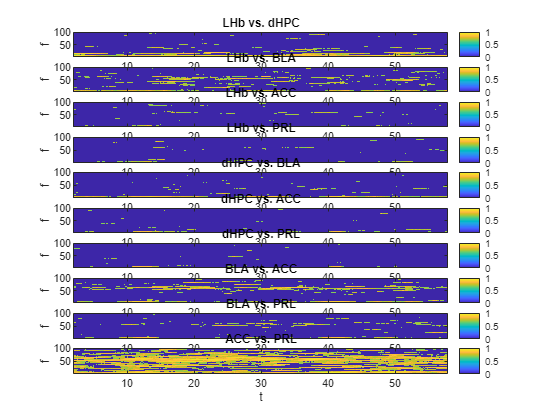

figure()
rat = 1;
for i = 1:length(matrixComp1)
    subplot(length(matrixComp1),1,i)
    tittle_coh = [coherency_list1{i}, ' vs. ', coherency_list2{i}];
    plotsig(C_smooth(:,:,i,rat),ConfC,tc,f_smooth,'jet'); axis xy; colorbar;title(tittle_coh)
    caxis([0 1]);
    ylim([1 100])
end

### Extract the coherence for the frequency band selected

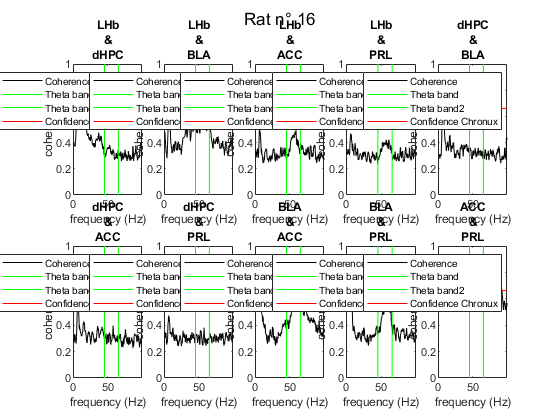

% Do the spectrogram - add stat
figure
rat = 1;
for i = 1: length(matrixComp1)
    subplot(2,5,i)
    plot(f_smooth,mean(C_smooth(:,:,i,rat),1),'k', 'DisplayName', 'Coherence');hold on
    line([lpf lpf],[0 1], 'Color', 'g', 'DisplayName', 'Theta band')
    line([hpf hpf],[0 1], 'Color', 'g', 'DisplayName', 'Theta band2')
    line([0 max(f_smooth)], [ConfC ConfC], 'Color', 'r','DisplayName', 'Confidence Chronux')
    title([coherency_list1(i), " & ", coherency_list2(i)])
    xlabel('frequency (Hz)')
    ylabel('coherence')
    legend
    sgtitle(sprintf('Rat n° %d',managing_sorted{1,rat}))
    axis('tight'); hold off
end

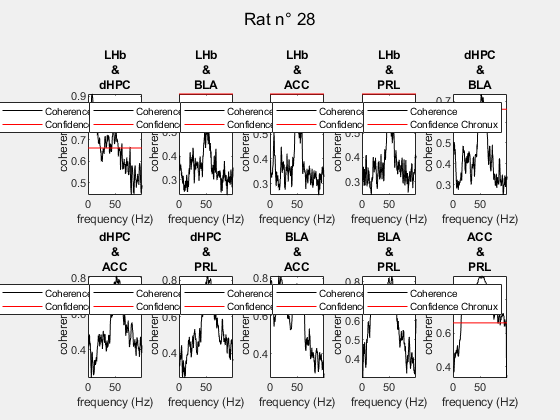

name_file = "coherancy_rat_16.fig"

name_file = "coherancy_rat_17.fig"

name_file = "coherancy_rat_18.fig"

name_file = "coherancy_rat_19.fig"

name_file = "coherancy_rat_13.fig"

name_file = "coherancy_rat_33.fig"

name_file = "coherancy_rat_32.fig"

name_file = "coherancy_rat_31.fig"

name_file = "coherancy_rat_30.fig"

name_file = "coherancy_rat_28.fig"



% Figures for each rat whitout displaying it
fcoh = figure('visible', 'off');

for rat = 1:length(managing_sorted(1,:))
    figure(fcoh)
    clf(fcoh)
    for i = 1:length(matrixComp1)
        subplot(2,5,i)
        plot(f_smooth,mean(C_smooth(:,:,i,rat),1),'k', 'DisplayName', 'Coherence');hold on
        line([0 max(f_smooth)], [ConfC ConfC], 'Color', 'r','DisplayName', 'Confidence Chronux')
        title([coherency_list1(i), " & ", coherency_list2(i)])
        xlabel('frequency (Hz)')
        ylabel('coherence')
        legend
        axis('tight'); hold off
    end

    sgtitle(sprintf('Rat n° %d',managing_sorted{1,rat}))
    name_file = sprintf("coherancy_rat_%d.fig",managing_sorted{1,rat})
    saveas(fcoh,fullfile(saving_path,"Figure",name_file))
end

#### Figure from the mean of the coherence across the rats

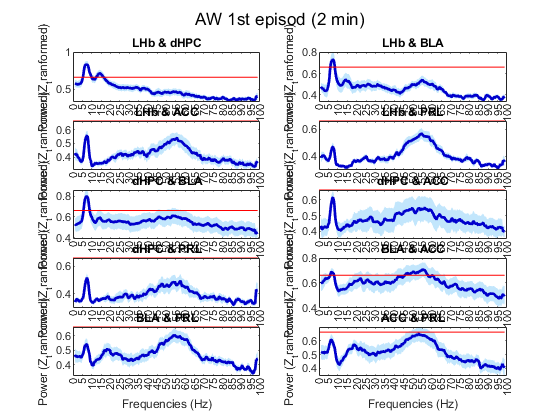

mean_coh = [];

for rat = 1:length(managing_sorted(1,:))
for i = 1: length(matrixComp1)
    mean_coh(rat,:,i) = mean(C_smooth(:,:,i,rat),1);
end
end

figcoh_mean = figure;

for i = 1: length(matrixComp1)
    figure(figcoh_mean)

    % Set plot paramiters
    option.color_area = rgb("LightSkyBlue");
    option.color_line = rgb("MediumBlue");
    option.x_axis = f_smooth;
    option.error = 'sem';
    option.handle = gcf;
    option.alpha      = 0.5;
    option.line_width = 2;
    subplot(5,2,i)
    plot_areaerrorbar(mean_coh(:,:,i), option) % function downloaded for mathsWorks (be carefull licence attached)
    
    xlim([0 100])
    xt = [0:5:100];                   % 'XTick' Values, bin between the number of the x axis
    set(gca, 'XTick', xt)             % Relabel 'XTick' With 'XTickLabel' Values
    xlabel('Frequencies (Hz)')
    ylabel('Power (Z_tranformed)')
    line([0 max(f_smooth)], [ConfC ConfC], 'Color', 'r')
    title(sprintf("%s & %s", coherency_list1{i}, coherency_list2{i}))
    sgtitle("AW 1st episod (2 min)")
    hold off
end


name_file = sprintf("Mean_coh_rat_AW1stEpisod.fig")

name_file = "Mean_coh_rat_AW1stEpisod.fig"

saveas(figcoh_mean,fullfile(saving_path,"Figure",name_file))

**Plot the mean of a cohelogram by time**

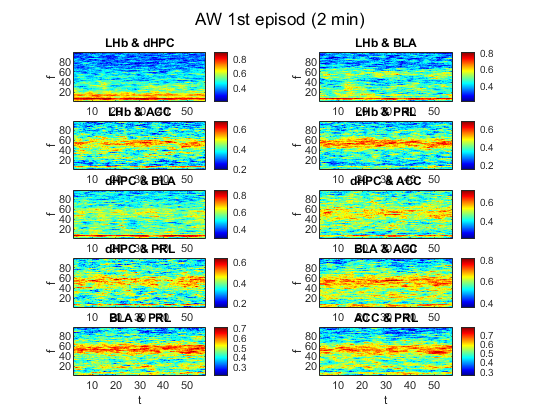

mean_coh_time = [];

for i = 1: length(matrixComp1)
    mean_coh_time(:,:,i) = mean(C_smooth(:,:,i,:),4);
end

figspect_time_mean = figure;

for i = 1: length(matrixComp1)
    figure(figspect_time_mean)
    subplot(5,2,i)
    plotsig(mean_coh_time(:,:,i),0,tc,f_smooth); axis xy; colorbar;colormap jet;  
    title(sprintf("%s & %s", coherency_list1{i}, coherency_list2{i}))
end
sgtitle("AW 1st episod (2 min)")
hold off


name_file = sprintf("Mean_coh_byTime_rat_AW1stEpisod.fig")

name_file = "Mean_coh_byTime_rat_AW1stEpisod.fig"

saveas(figspect_time_mean,fullfile(saving_path,"Figure",name_file))

### Extract the theta coherence

#### Low pass filter (5-9 theta & 1-3 delta)

lpf = 9

lpf = 9

#### High pass filter 

hpf = 5

hpf = 5

data_coh =[];
int_data_coh =NaN(length(managing_sorted(1,:)),10); 

% find the sampling rate
Fs_freq = length(fc(1,:))/max(fc(1,:))

Fs_freq = 7.3772


stop_freq_bd = round(lpf*Fs_freq);      %in points (positions)
start_freq_bd = round(hpf*Fs_freq);     %in points (positions)

for rat = 1:length(list_rat)
for i = 1: length(matrixComp1)
    data_coh = mean(C(:,:,i,rat),1);
    data_coh = data_coh(:,start_freq_bd:stop_freq_bd);
    
    freq_new_scale = fc(:,start_freq_bd:stop_freq_bd);

    int_data_coh(rat,i) = mean(data_coh);
end
end

int_data_coh_full = int_data_coh;

for rat = 1:length(list_rat)
for i = 1: length(matrixComp1)
    if int_data_coh_full(rat,i)<= ConfC 
        int_data_coh_full(rat,i) = NaN;
    end
end
end


title_coh={};
for i = 1: length(matrixComp1)
    title_coh{i,1} = sprintf('%s & %s', coherency_list1{i}, coherency_list2{i});
end

T_coh_theta = array2table(int_data_coh, 'VariableNames',title_coh ,'RowNames', list_rat) 

T_coh_theta = 10×10 table
          LHb & dHPC    LHb & BLA    LHb & ACC    LHb & PRL    dHPC & BLA    dHPC & ACC    dHPC & PRL    BLA & ACC    BLA & PRL    ACC & PRL
          __________    _________    _________    _________    __________    __________    __________    _________    _________    _________

    16     0.80725       0.61061      0.43077      0.41993      0.65591       0.48214       0.41429       0.63304      0.55996      0.82692 
    17     0.50761       0.47778      0.39657      0.34399      0.76499       0.60106       0.47748       0.56711      0.47282      0.52779 
    18     0.89787

name_file = sprintf("Table_coh_theta.xlsx")

name_file = "Table_coh_theta.xlsx"

writetable(T_coh_theta,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

T_coh_full_theta = array2table(int_data_coh_full, 'VariableNames',title_coh ,'RowNames', list_rat) 

T_coh_full_theta = 10×10 table
          LHb & dHPC    LHb & BLA    LHb & ACC    LHb & PRL    dHPC & BLA    dHPC & ACC    dHPC & PRL    BLA & ACC    BLA & PRL    ACC & PRL
          __________    _________    _________    _________    __________    __________    __________    _________    _________    _________

    16     0.80725           NaN        NaN          NaN            NaN           NaN         NaN             NaN          NaN      0.82692 
    17         NaN           NaN        NaN          NaN        0.76499           NaN         NaN             NaN          NaN          NaN 
    18     0.

name_file = sprintf("Table_coh_theta_NaN.xlsx")

name_file = "Table_coh_theta_NaN.xlsx"

writetable(T_coh_full_theta,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);



### Extract the gamma coherence

#### Low pass filter 

lpf = 65

lpf = 65

#### High pass filter 

hpf = 45

hpf = 45

data_coh =[];
int_data_coh =NaN(length(managing_sorted(1,:)),10); % rat * channels

% find the sampling rate
Fs_freq = length(fc(1,:))/max(fc(1,:))

Fs_freq = 7.3772


stop_freq_bd = round(lpf*Fs_freq);      %in points (positions)
start_freq_bd = round(hpf*Fs_freq);     %in points (positions)

for rat = 1:length(list_rat)
for i = 1: length(matrixComp1)
    data_coh = mean(C(:,:,i,rat),1);
    data_coh = data_coh(:,start_freq_bd:stop_freq_bd);
    
    freq_new_scale = fc(:,start_freq_bd:stop_freq_bd);

    int_data_coh(rat,i) = mean(data_coh);
end
end

int_data_coh_full = int_data_coh;

for rat = 1:length(list_rat)
for i = 1: length(matrixComp1)
    if int_data_coh_full(rat,i)<= ConfC 
        int_data_coh_full(rat,i) = NaN;
    end
end
end


title_coh={};
for i = 1: length(matrixComp1)
    title_coh{i,1} = sprintf('%s & %s', coherency_list1{i}, coherency_list2{i});
end

T_coh_gamma = array2table(int_data_coh, 'VariableNames',title_coh ,'RowNames', list_rat) 

T_coh_gamma = 10×10 table
          LHb & dHPC    LHb & BLA    LHb & ACC    LHb & PRL    dHPC & BLA    dHPC & ACC    dHPC & PRL    BLA & ACC    BLA & PRL    ACC & PRL
          __________    _________    _________    _________    __________    __________    __________    _________    _________    _________

    16      0.3261        0.5329      0.39566      0.36491      0.32511       0.30692       0.30284       0.57119      0.48405      0.78086 
    17     0.34334       0.53046      0.36914      0.55297      0.35916       0.33963       0.44136       0.41367       0.6639      0.42695 
    18      0.5488

name_file = sprintf("Table_coh_gamma.xlsx")

name_file = "Table_coh_gamma.xlsx"

writetable(T_coh_gamma,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

T_coh_full_gamma = array2table(int_data_coh_full, 'VariableNames',title_coh ,'RowNames', list_rat) 

T_coh_full_gamma = 10×10 table
          LHb & dHPC    LHb & BLA    LHb & ACC    LHb & PRL    dHPC & BLA    dHPC & ACC    dHPC & PRL    BLA & ACC    BLA & PRL    ACC & PRL
          __________    _________    _________    _________    __________    __________    __________    _________    _________    _________

    16         NaN           NaN          NaN          NaN          NaN           NaN           NaN           NaN          NaN      0.78086 
    17         NaN           NaN          NaN          NaN          NaN           NaN           NaN           NaN       0.6639          NaN 
    18       

name_file = sprintf("Table_coh_gamma_NaN.xlsx")

name_file = "Table_coh_gamma_NaN.xlsx"

writetable(T_coh_full_gamma,fullfile(saving_path,name_file),'Sheet',sprintf("%s_%s", session_name, subsession_name), 'WriteRowNames',true);

Saving the variable needed

name_file = sprintf("AW2min1st_%s_Theta_var.mat", session_name)

name_file = "AW2min1st_HAB3_Theta_var.mat"

save(fullfile(saving_path,name_file), 'list_rat','LFP_cl_full','Stot_Z','ttot','ftot','titles','srate','T_peak_theta','T_power_theta', ...
    'T_power_gamma', ...
    'T_peak_gamma','coherency_list1','coherency_list2', 'matrixComp1','matrixComp2','C_smooth','f_smooth','tc','T_coh_theta','T_coh_full_theta', ...
    'T_coh_gamma','T_coh_full_gamma')

toc

Elapsed time is 256.443161 seconds.


# Functions definition part

function [LFP_full, Table_sumary] = selection_period(managing_sorted,LFP,srate,time, condition, wanted_state, after_state)

LFP_full = [];
LFP_interest = {};

ep_list = [];
time_point_ep = [];
length_ep = [];

condition = categorical(condition);

    for i = 1 :length(managing_sorted(1,:))
        
        if condition == "after"
            %Find the first episode of sleep
            first_sleep_end = LFP.(after_state){2,i}{1,3};
            
            % Add the rat number into the cell array
            LFP_interest{1,i} = managing_sorted{1,i};
        
            % Find the AW episod next to this time (use while loop)
            % iniate the episod count
            ep_interest = 1;
            % find the episode after the time of the first episode of sleep
            while LFP.(wanted_state){2,i}{ep_interest,2} <= first_sleep_end
                ep_interest = 1 + ep_interest;
            end
            length_LFP = length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:));
            
            % put the episod corresponding into the cell array of the results
            LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};
        
            % while loop : while the time is shorter than the time set or the end
            % is reached put the new episod into the results cell array
            while (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)) && ep_interest<length(LFP.(wanted_state){2,i}(:,1))
                ep_interest = ep_interest + 1;    
                LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};
                length_LFP = [length_LFP length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))];
            end
            
            % print the number of the episod selected and the number of time
            % (extenssion should add the time of the begging of the episod)
            fprintf("Rat n°%d = Episod number : %2.0f \r\n", managing_sorted{1,i}, ep_interest)

            

        
            % if no episode correspond to the criterias then writte it down and
            % indicate the longer episod possible after the first sleep period
            if length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)
                warning(sprintf("No episod have been found. Max length : %4.2f s \r\n", max(length_LFP)/srate))
        
                % replace the LFP results as NaN - because the criteria does not
                % match
                LFP_interest{2,i} = NaN(length(LFP.(wanted_state){2,i}{ep_interest,1}(:,1)),time*srate);

                ep_list = [ep_list; NaN];
                time_point_ep = [time_point_ep; NaN];
                length_ep = [length_ep; NaN];

            else 
                % Keep the time of the episod selected and the number of the
                % episod
                ep_list = [ep_list; ep_interest];
                time_point_ep = [time_point_ep; LFP.(wanted_state){2,i}{ep_interest,2}];
                length_ep = [length_ep; (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))/srate)];
            end


            % Put the data into a matrix to match the following script
            LFP_full(:,:,i) = LFP_interest{2,i}(:,1:time*srate); % Matrix 3D with rats are the 3th D (channel * time * rat)



        elseif condition == "first"
            LFP_interest{1,i} = managing_sorted{1,i};
            ep_interest = 1;
            length_LFP = length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:));
            LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};

            while (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)) && ep_interest<length(LFP.(wanted_state){2,i}(:,1))
                ep_interest = ep_interest + 1;    
                LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};
                length_LFP = [length_LFP length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))];
            end
            fprintf("Rat n°%d = Episod number : %2.0f \r\n", managing_sorted{1,i}, ep_interest)
            if length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)
                warning(sprintf("No episod have been found. Max length : %4.2f s \r\n", max(length_LFP)/srate))

                ep_list = [ep_list; NaN];
                time_point_ep = [time_point_ep; NaN];
                length_ep = [length_ep; NaN];
        
                % replace the LFP results as NaN - because the criteria does not
                % match
                LFP_interest{2,i} = NaN(length(LFP.(wanted_state){2,i}{ep_interest,1}(:,1)),time*srate);
            else 
                % Keep the time of the episod selected and the number of the
                % episod
                ep_list = [ep_list; ep_interest];
                time_point_ep = [time_point_ep; LFP.(wanted_state){2,i}{ep_interest,2}];
                length_ep = [length_ep; (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))/srate)];
            
            end
            LFP_full(:,:,i) = LFP_interest{2,i}(:,1:time*srate); % Matrix 3D with rats are the 3th D (channel * time * rat)

        elseif condition == "last"
            LFP_interest{1,i} = managing_sorted{1,i};

            max_ep = length(LFP.(wanted_state){2,i}(:,1));
            ep_interest = max_ep;

            length_LFP = length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:));
            LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};

            while (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)) && ep_interest >1
                ep_interest = ep_interest - 1;    
                LFP_interest{2,i} = LFP.(wanted_state){2,i}{ep_interest,1};
                length_LFP = [length_LFP length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))];
            end

            fprintf("Rat n°%d = Episod number : %2.0f \r\n", managing_sorted{1,i}, ep_interest)
            if length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:)) <= (time*srate)
                warning(sprintf("No episod have been found. Max length : %4.2f s \r\n", max(length_LFP)/srate))

                ep_list = [ep_list; NaN];
                time_point_ep = [time_point_ep; NaN];
                length_ep = [length_ep; NaN];
        
                % replace the LFP results as NaN - because the criteria does not
                % match
                LFP_interest{2,i} = NaN(length(LFP.(wanted_state){2,i}{ep_interest,1}(:,1)),time*srate);

            else 
                % Keep the time of the episod selected and the number of the
                % episod
                ep_list = [ep_list; ep_interest];
                time_point_ep = [time_point_ep; LFP.(wanted_state){2,i}{ep_interest,2}];
                length_ep = [length_ep; (length(LFP.(wanted_state){2,i}{ep_interest,1}(1,:))/srate)];
            end

            LFP_full(:,:,i) = LFP_interest{2,i}(:,1:time*srate); % Matrix 3D with rats are the 3th D (channel * time * rat)

        end
        
        % create the list of the rat
        list_rat = [];
        for rat = 1:length(managing_sorted(1,:))
            list_rat = [list_rat; managing_sorted{1,rat}];
        end
    
    end

    Table_sumary = table(list_rat, ep_list, time_point_ep, length_ep, 'VariableNames',{'Rats', 'Episod number', 'Episod start (s)', 'Episod length (s)'})

end



function [LFP, table_nb_period, srate] = extract_the_data(managing_sorted,pathway_source, session_name,subsession_name)
LFP.AW = {};
LFP.CW = {};
LFP.SWS = {};
LFP.REM = {};
LFP.sleeptrack = [];

nb_period_rat ={};
nb_period_AW =[];
nb_period_CW =[];
nb_period_SWS =[];
nb_period_REM =[];

for i = 1 :length(managing_sorted(1,:))
    
    LPF_AW = {} ;
    LPF_CW = {} ;
    LPF_SWS = {} ;
    LPF_REM = {} ;

    SleepTrack_full = [];

    % Indique which rat is took in account
    current_rat = managing_sorted{1,i}(1,1)

    for h = 1:3
        
        % Set the pathway to the folder containing the data
        current_hour = h;
        nameFolder1 = [num2str(cell2mat(managing_sorted(1,i))),session_name,subsession_name];
        nameFolder2 = ['stage_extraction_hour',num2str(current_hour)];
        nameFile = ['Stages_assessed_hours',num2str(current_hour),'.mat'];
        
        % Load the data
        load(fullfile(pathway_source,nameFolder1,nameFolder2,nameFile));

        % Put the data together over the 3 hours
        if h == 1
            LPF_AW = Results.local.AW(:,:);
            LPF_CW = Results.local.CW(:,:);
            LPF_SWS = Results.local.SWS(:,:);
            LPF_REM = Results.local.REM(:,:);
        elseif h == 2

            if isempty(Results.local.AW) == 0
            for time = 1:length(Results.local.AW(:,1))
                Results.local.AW{time,2}(1,1) = Results.local.AW{time,2}(1,1) + 1*3599;
                Results.local.AW{time,3}(1,1) = Results.local.AW{time,3}(1,1) + 1*3599;
            end
            end
            LPF_AW = [LPF_AW; Results.local.AW];
            
            if isempty(Results.local.CW) == 0
            for time = 1:length(Results.local.CW(:,1))
                Results.local.CW{time,2}(1,1) = Results.local.CW{time,2}(1,1) + 1*3599;
                Results.local.CW{time,3}(1,1) = Results.local.CW{time,3}(1,1) + 1*3599;
            end
            end
            LPF_CW = [LPF_CW; Results.local.CW];

            if isempty(Results.local.SWS) == 0
            for time = 1:length(Results.local.SWS(:,1))
                Results.local.SWS{time,2}(1,1) = Results.local.SWS{time,2}(1,1) + 1*3599;
                Results.local.SWS{time,3}(1,1) = Results.local.SWS{time,3}(1,1) + 1*3599;
            end
            end
            LPF_SWS = [LPF_SWS; Results.local.SWS];


            if isempty(Results.local.REM) == 0
            for time = 1:length(Results.local.REM(:,1))
                Results.local.REM{time,2}(1,1) = Results.local.REM{time,2}(1,1) + 1*3599;
                Results.local.REM{time,3}(1,1) = Results.local.REM{time,3}(1,1) + 1*3599;
            end
            end
            LPF_REM = [LPF_REM; Results.local.REM];
        
        else 
            if isempty(Results.local.AW) == 0
            for time = 1:length(Results.local.AW(:,1))
                Results.local.AW{time,2}(1,1) = Results.local.AW{time,2}(1,1) + 2*3599;
                Results.local.AW{time,3}(1,1) = Results.local.AW{time,3}(1,1) + 2*3599;
            end
            end
            LPF_AW = [LPF_AW; Results.local.AW];
            
            if isempty(Results.local.CW) == 0
            for time = 1:length(Results.local.CW(:,1))
                Results.local.CW{time,2}(1,1) = Results.local.CW{time,2}(1,1) + 2*3599;
                Results.local.CW{time,3}(1,1) = Results.local.CW{time,3}(1,1) + 2*3599;
            end
            end
            LPF_CW = [LPF_CW; Results.local.CW];

            if isempty(Results.local.SWS) == 0
            for time = 1:length(Results.local.SWS(:,1))
                Results.local.SWS{time,2}(1,1) = Results.local.SWS{time,2}(1,1) + 2*3599;
                Results.local.SWS{time,3}(1,1) = Results.local.SWS{time,3}(1,1) + 2*3599;
            end
            end
            LPF_SWS = [LPF_SWS; Results.local.SWS];


            if isempty(Results.local.REM) == 0
            for time = 1:length(Results.local.REM(:,1))
                Results.local.REM{time,2}(1,1) = Results.local.REM{time,2}(1,1) + 2*3599;
                Results.local.REM{time,3}(1,1) = Results.local.REM{time,3}(1,1) + 2*3599;
            end
            end
            LPF_REM = [LPF_REM; Results.local.REM];

        end
        
        SleepTrack_full = [SleepTrack_full SleepTrack];

  
    end
    
    
    LFP.sleeptrack{1,i} = current_rat;
    LFP.sleeptrack{2,i} = SleepTrack_full;

    LFP.AW{1,i} = current_rat;
    LFP.AW{2,i} = LPF_AW;

    LFP.SWS{1,i} = current_rat;
    LFP.SWS{2,i} = LPF_SWS;

    LFP.CW{1,i} = current_rat;
    LFP.CW{2,i} = LPF_CW;

    LFP.REM{1,i} = current_rat;
    LFP.REM{2,i} = LPF_REM;
    
    nb_period_rat{1,i} = num2str(current_rat);
    nb_period_AW = [nb_period_AW; length(LPF_AW(:,1))];
    nb_period_CW = [nb_period_CW; length(LPF_CW(:,1))];
    nb_period_SWS = [nb_period_SWS; length(LPF_SWS(:,1))];
    nb_period_REM = [nb_period_REM; length(LPF_REM(:,1))];

end

srate = ElectParams.New_SR;

table_nb_period = table(nb_period_AW,nb_period_CW, nb_period_SWS, nb_period_REM, ...
    'VariableNames', ["AW","CW","SWS","REM"],'RowNames', nb_period_rat)
end
